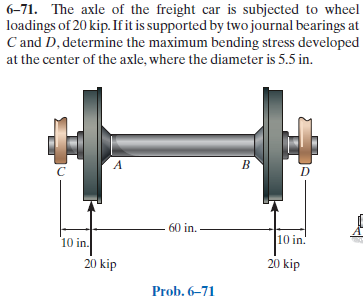

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-71P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-71P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Rc', 0);
b = b.add('concentrated', 'force', 20*u.kip, 10*u.in);
b = b.add('concentrated', 'force', 20*u.kip, 70*u.in);
b = b.add('reaction', 'force', 'Rd', 80*u.in);
b.L = 80*u.in;

# section properties

D = 5.5*u.in;
b.I = sympi*(D/2)^4/4;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{10240\,x\,\left(2100\,{\mathrm{in}}^{2}-x^{2}\right)}{43923\,\text{E}\,\pi }\,\frac{\mathrm{kip}}{{\mathrm{in}}^{4}} & \text{ if }x\leq 10\,\mathrm{in}\\ -\frac{102400\,\left(3\,x^{2}-240\,x\,\mathrm{in}+100\,{\mathrm{in}}^{2}\right)}{43923\,\text{E}\,\pi }\,\frac{\mathrm{kip}}{{\mathrm{in}}^{3}} & \text{ if }x\in \left(10\,\mathrm{in},70\,\mathrm{in}\right]\\ \frac{10240\,\left(x-80\,\mathrm{in}\right)\,\left(x^{2}-160\,x\,\mathrm{in}+4300\,{\mathrm{in}}^{2}\right)}{43923\,\text{E}\,\pi }\,\frac{\mathrm{kip}}{{\mathrm{in}}^{4}} & \text{ if }70\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{10240\,\left(700\,{\mathrm{in}}^{2}-x^{2}\right)}{14641\,\text{E}\,\pi }\,\frac{\mathrm{kip}}{{\mathrm{in}}^{4}} & \text{ if }x\leq 10\,\mathrm{in}\\ -\frac{204800\,\left(x-40\,\mathrm{in}\right)}{14641\,\text{E}\,\pi }\,\frac{\mathrm{kip}}{{\mathrm{in}}^{3}} & \text{ if }x\in \left(10\,\mathrm{in},70\,\mathrm{in}\right]\\ \frac{10240\,\left(x^{2}-160\,x\,\mathrm{in}+5700\,{\mathrm{in}}^{2}\right)}{14641\,\text{E}\,\pi }\,\frac{\mathrm{kip}}{{\mathrm{in}}^{4}} & \text{ if }70\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -20\,x\,\mathrm{kip} & \text{ if }x\leq 10\,\mathrm{in}\\ -200\,\mathrm{in}\,\mathrm{kip} & \text{ if }x\in \left(10\,\mathrm{in},70\,\mathrm{in}\right]\\ 20\,\left(x-80\,\mathrm{in}\right)\,\mathrm{kip} & \text{ if }70\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -20\,\mathrm{kip} & \text{ if }x\leq 10\,\mathrm{in}\\ 0 & \text{ if }x\in \left(10\,\mathrm{in},70\,\mathrm{in}\right]\\ 20\,\mathrm{kip} & \text{ if }70\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rc} & -20\,\mathrm{kip}\\ \mathrm{Rd} & -20\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

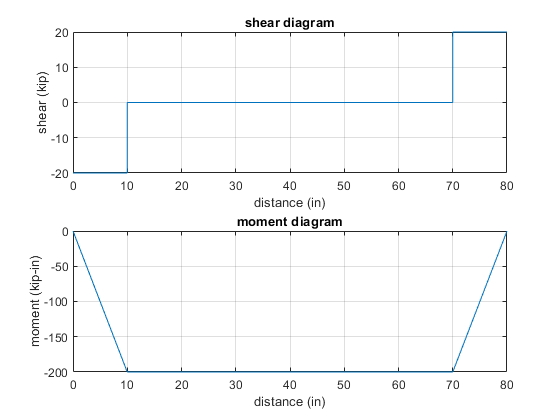

beam.shear_moment(m, v, [0 b.L], {'kip' 'in'});

# maximum bending stress

M_max = m(40*u.in)

$$M\_max = -200\,\mathrm{in}\,\mathrm{kip}$$

C = D/2;
sigma_max = rewrite(-M_max*C/b.I, u.ksi);
sigma_max_vpa = vpa(sigma_max, 4) %#ok<NASGU> 

$$sigma\_max\_vpa = 12.24\,\mathrm{ksi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear sigma_max_vpa;